clear

%params
freq = 2.5e9;
c = 3e8;
wavelen = c/freq;
nAntennas = 16;
d2d = wavelen/2;

% define antenna coordinates
coords = linspace(0, d2d*nAntennas, nAntennas)

coords =          0    0.0640    0.1280    0.1920    0.2560    0.3200    0.3840    0.4480    0.5120    0.5760    0.6400    0.7040    0.7680    0.8320    0.8960    0.9600



sv = @(azim) exp(-j*pi.*(0:nAntennas)'.*cos(deg2rad(azim)))

sv = function_handle with value:
    @(azim)exp(-j*pi.*(0:nAntennas)'.*cos(deg2rad(azim)))


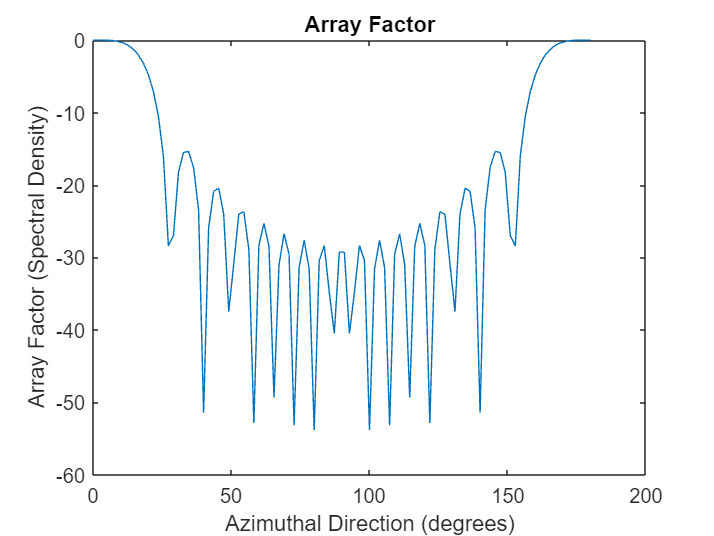

aoa=0;

azim_basis = linspace(0, 180);
AF = zeros(length(azim_basis));
error = zeros(length(azim_basis));

for j = 1:length(azim_basis);
    azim_doa = azim_basis(j);

    for i = 1:length(azim_basis);
    
        azim_i = azim_basis(i);
        % case where steering vector is the same as wei
        steering_vector = sv(azim_i).*sv(-azim_doa) ;
        AF_i = sum(steering_vector/nAntennas);
        AF(i) = -AF_i;
    
    end
    
    AF = 10*log(abs(AF)/max(abs(AF)));
    
    length(AF);
    plot(azim_basis, (AF))
    title("Array Factor")
    xlabel("Azimuthal Direction (degrees)")
    ylabel("Array Factor (Spectral Density)")
    pause(0.1)

    max_i = find(max(AF)==AF,1);
    aoa_calc = azim_basis(max_i);

    error(j) = azim_doa-aoa_calc;
end

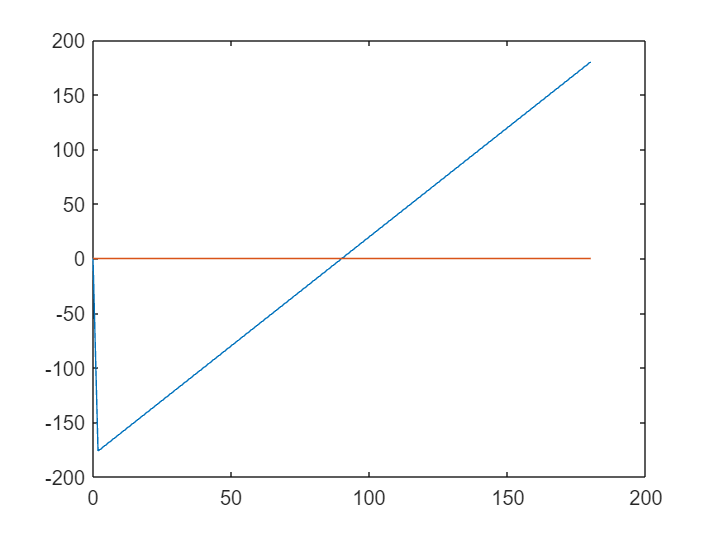


plot(azim_basis, error)


mean(error)

ans =     1.8000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
